Here is the main code:

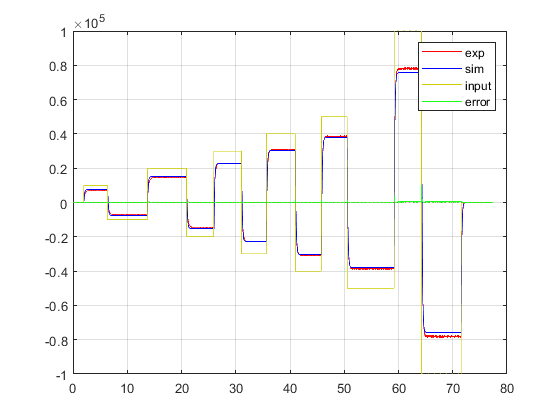

    2.1495



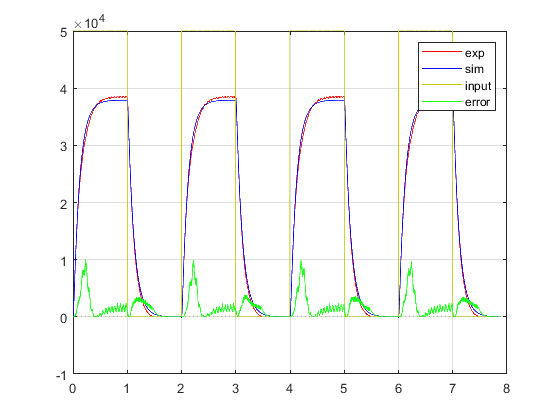

    2.3639



experiments = {load("proveSperimentali/scalini.mat").data032, load("proveSperimentali/square.mat").data011};
        % in experiments there are the input files that have to be analized
Tf = fitData(experiments, 2, NaN); % if there's an initial system that tfest use at the beginning
plotConfront(experiments, Tf);

Here we define some utility functions that will help us to speed up the analisys

function tf = fitData(exps, np, init_sys)  % experiments must have the same sampling times and time step must be fixed
    scarto = 1; % the last input should be deleted
    y = {};
    u = {};
    Ts = -1;
    for i = 1:size(exps(:))
        e = exps{i};
        y = { y, e(4,1:end-scarto)' };
        u = { u, e(2,1:end-scarto)' };
        if Ts == -1
            Ts = e(1,2) - e(1,1);
        elseif Ts ~= e(1,2) - e(1,1)
            Ts = -2;   % different time steps across experiments are not allowed
        end
    end
    
    y{1} = y{1,2};
    u{1} = u{1,2};
    
    if Ts == -2
        tf = null;
    else
        data = iddata(y, u, Ts);
        opt = tfestOptions;
        opt.Display = 'on';
        opt.SearchMethod = 'auto';
        opt.SearchOptions.Tolerance = 0.0001;
        opt.SearchOptions.MaxIterations = 50; % more iterations get no gain
        if np > -1
            tf = tfest(data, np, opt); 
        else
            tf = tfest(data, init_sys, opt);
        end
        
    end
    
end


function plotConfront(experiments, tf)
    red    = [1, 0, 0];
    blue   = [0, 0, 1];
    yellow = [0.8, 0.8, 0];
    green  = [0.1, 1, 0.1];
    scale = 1e4; %to a better view on the plot
    eps = 1;
    scarto = 1;
    
    num = size(experiments);
    num = num(2);
    for i = 1:num
        t = experiments{i}(1,1:end-scarto);
        u = experiments{i}(2,1:end-scarto);
        y_exp = experiments{i}(4,1:end-scarto);
        
        y_sim = lsim(tf, u, t);
        figure;
        plot(t, y_exp, 'Color', red);
        hold on;
        plot(t, y_sim, 'Color', blue);
        hold on;
        plot(t, u*scale, 'Color', yellow);
        hold on;
        errors = abs(y_exp-y_sim');
        max_error = max(errors');
        plot(t, (errors.^2./(max_error^2))*scale, 'Color', green); 
        hold on;
        plot(t, zeros(size(t)), ':');
        hold on;
        legend({'exp', 'sim', 'input', 'error'});
        grid on;
        
        %MSE = mean((y_exp - y_sim').^2);    % consider normalization
        max_f = max(y_exp);
        nMSE = mean(errors.^2/(max_f^2))*1e4;
        %nMSE = mean(((y_exp - y_sim')./(y_exp + eps)).^2);  %normalized MSE
        disp(nMSE)
    end
end